clear;clc;close all
layerfolder='../data/layers/';%Route to folder with ambiental data
Dimensions = ReadLayers(layerfolder); %The 19 environmental variables for all the map

----Reading layers----
Elapsed time is 10.865358 seconds.


InfoInitialPoint = InitialPoint(Dimensions, 'beta'); %Generate a initial point to generate a niche

Elapsed time is 22.652828 seconds.


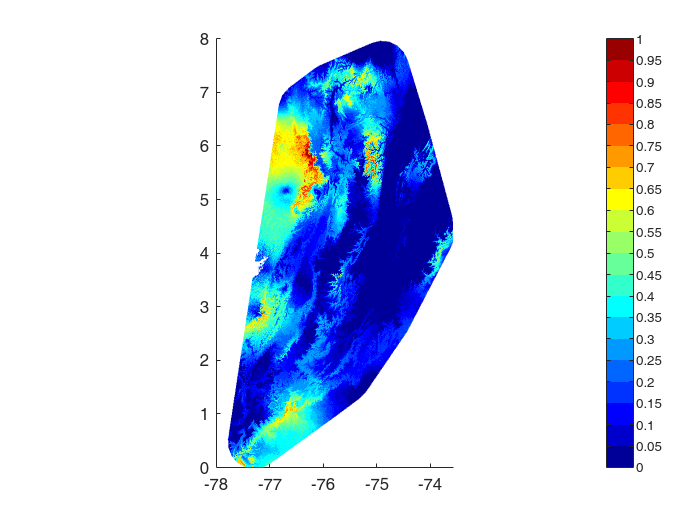

MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.8, true); %Generate the niche based on the initial point

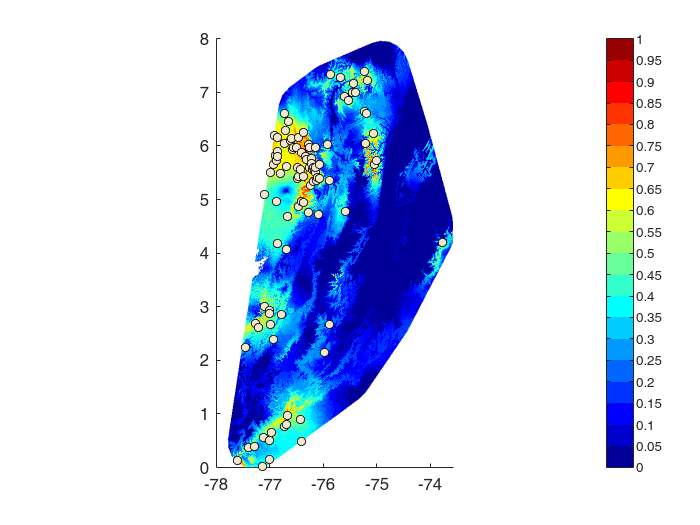

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 100, -3, true, 'GenSP', true, true); %Generate samples based on the generated niche

close all, clf
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers

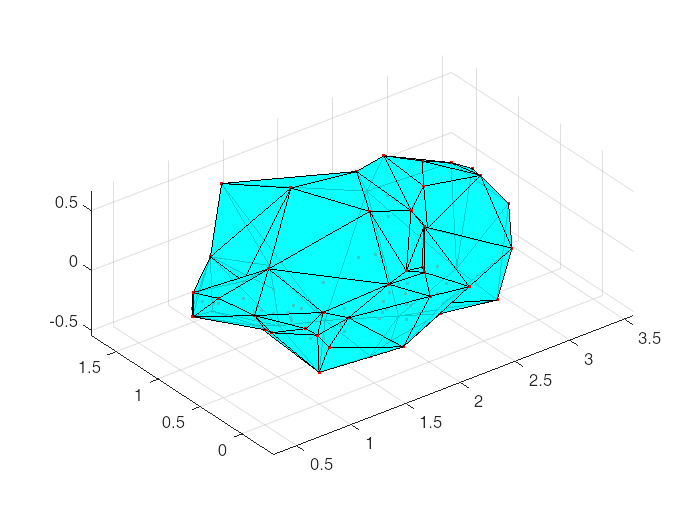

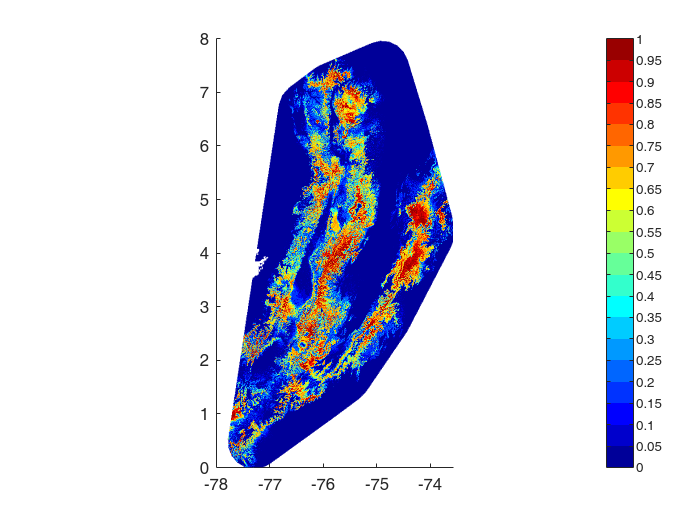

%ColoringBorder generates classifier object with atributes nodes = environmental variables
%for each frontier point, 
%T = table with samples and information
%readInfo = dimensions of the map
%alpha = shrinking factor

classA1 = ColoringBorder(T,Dimensions,1,show,outlier,outlier2); 

classA2 = ColoringWeightedBorder(T,Dimensions,1,show,outlier,outlier2);

BorderWeights =     0.0909
    0.0909
    0.0909
    0.0909
    0.1818
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909


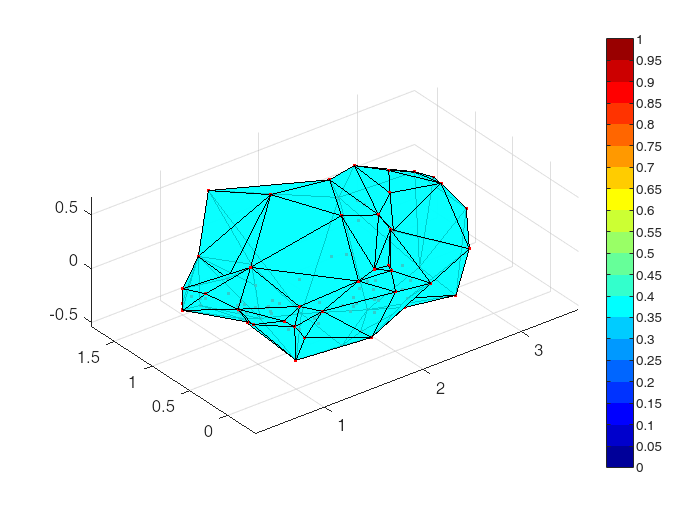

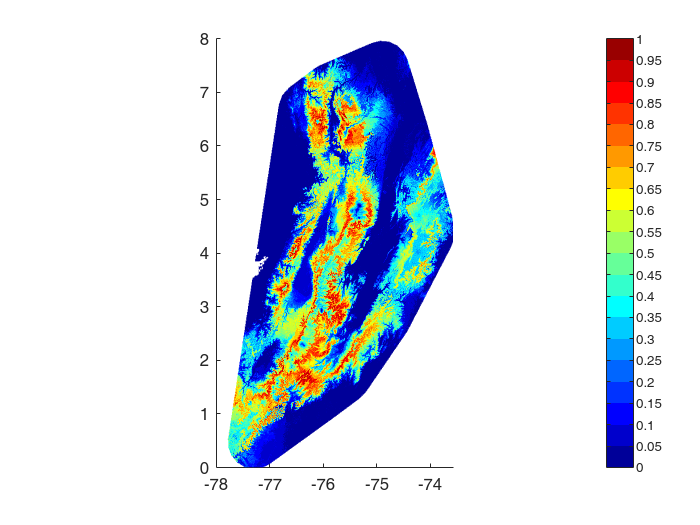

%T = table with samples and information
%readInfo = dimensions of the map
%percentile = percentile with which the radius will be taken
%alpha = shrinking factor

classB1 = ColoringRadius(T,Dimensions,1,50,show,outlier,outlier2); 

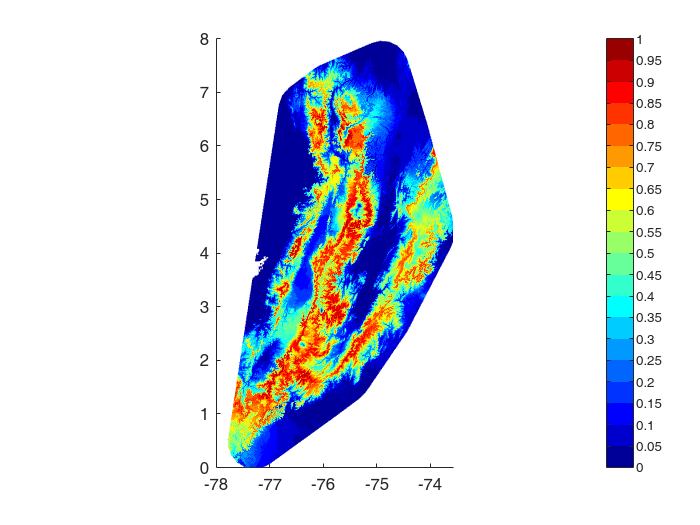

classB2 = ColoringRadiusPercentile(T,Dimensions,1,50,true,false,false); 

MapMetric(MapInfo.Map,classA2.map,false) %accuracy of the generated colored map compared to the the original niche

ans =     0.8247   -1.0863


MapMetric(MapInfo.Map,classB.map,false) 

Unable to resolve the name 'classB.map'.

MapMetric(MapInfo.Map,classC.map,false) 

InfoInitialPoint = InitialPoint(Dimensions, 'beta'); %Generate a initial point to generate a niche

Elapsed time is 20.903689 seconds.


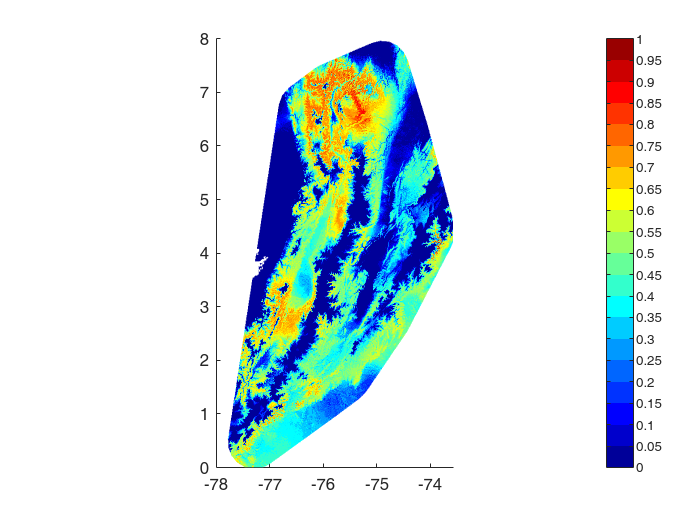

MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.8, true);

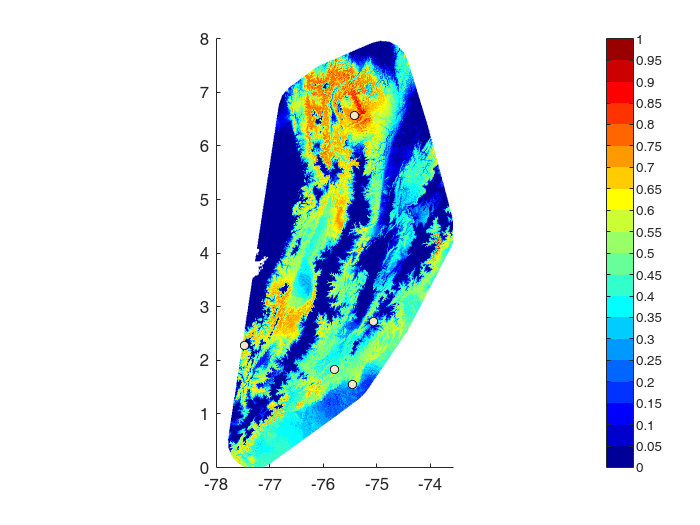

% Puntos core: 4c para el metodo hecho mal para blindar el metodo
% Calcular la distancia desde PCA3: metodo bien hecho
% Promediar todos los radios
% Contaminar los datos
% Probar con el metodo de Luisa
% Metodo para crear datos nuevos